# Glider V-n Daigram

clear; close all; clc;

## Define Values For Maniver Diagram

% for program development we will use the DG-1000T Data

W_MGTO = 7354.9875; % Maximum Gross Takeoff Weight (N)
W_gross = W_MGTO; % Gorss Wegiht (N)
W_oe = W_gross; % operating empty weight (N)
category = "Aerobatic Glider"; % Max g limit catregory
S = 17.53; % Wing Area (m^2)
A = 22.82; % aspect ratio (~)
Lambda_LE = deg2rad(-2); % leading edge sweep angle (radians)
lambda = .5/2.1; % taper ratio (~)
M = 0; % Mach number (~) (for incompressible M = 0)
alpha_stall = deg2rad(15); % stall angle (radians)
alt = 0; % altitude (m)

% Here is the Data for our Aircraft
W_MGTO = 9159; % Maximum Gross Takeoff Weight (N)
W_gross = W_MGTO; % Gorss Wegiht (N)
W_oe = W_gross; % operating empty weight (N)
category = "Aerobatic Glider"; % Max g limit catregory
S = 17.53; % Wing Area (m^2)
A = 22.82; % aspect ratio (~)

% for now i am assuming sea level -clarify this with Dr. Barrett
[~, ~, ~, rho] = atmosisa(0); % atmospheric density (kg/m^3)


% note: was unable to find data for the DG-1000 airfoild so used the
% ASW-22's airfoild which is a DU84-132v3 - then assuemd C_l_alpha is flat
% plate is 2 pi
C_l_alpha = 2*pi % lift curve slope of flat plate

C_l_alpha = 6.2832


V_max_plot = 80; % maximum velocity to plot (m/s)
n_plot_points = 100; % number of points to plot (~)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% gust diagram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

W_TO = W_MGTO;
c_bar  = .877; % c_bar (m) DG 1000T
g = 9.81; % acceleration due to gravity in (m/s)

## Maneuver Diagram

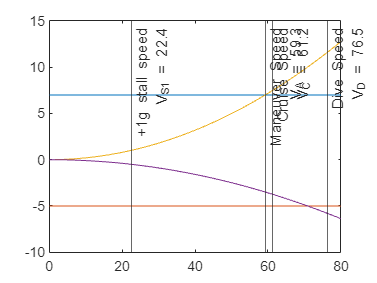

% Determine Aircraft Parameters
%find C_L_max
C_L_alpha = polhamus(C_l_alpha, A, Lambda_LE, lambda, M);
C_L_max = C_L_alpha .* C_l_alpha ./ (2*pi) .* alpha_stall;

%Velocities for plotting
V = linspace(0, V_max_plot, n_plot_points);

% determine the Maximum and Minimum manuver loads 
[n_lim_pos, n_lim_neg] = LoadFactor_ManuverLimit_FAR23(W_gross, category);
%n_lim_pos = 10; n_lim_neg = -9; % for the swift s1

n_lim_pos_array = repelem(n_lim_pos, length(V));
n_lim_neg_array = repelem(n_lim_neg, length(V));
plot(V, n_lim_pos_array); hold on
plot(V, n_lim_neg_array);

% determin low speed manuver limits
n_lim_pos_lowSpeed = 1.1 * rho .* V.^2 .* S .* C_L_max ./ (2 * W_oe);
n_lim_neg_lowSpeed = -.5 * n_lim_pos_lowSpeed;

plot(V, n_lim_pos_lowSpeed); hold on
plot(V, n_lim_neg_lowSpeed);

% find 1g stall speed
V_S1 = sqrt(2 * W_oe ./ (1.1 * rho .* S .* C_L_max)); % 1g stall speed (m/s)
% note this is aproximatly what the cited values for the DG-1000T are

% find minimum maneuver speed
V_A = V_S1 .* sqrt(n_lim_pos); % maneuver speed (m/s)
xline(V_A, "-", {"Maneuver Speed", sprintf("V_A = %.3g",V_A)}); % plot manuver speed
xline(V_S1, "-", {"+1g stall speed", sprintf("V_{S1} = %.3g",V_S1)}); % plot 1g stall speed

% determine minimum cruise speed
W2S_cuttoff = convpres(20,"psf","Pa"); % cutoff for FAR 23 between low and high k_c

% unit conversion factor for k_c
kts2fps = convvel(1,"kts","ft/s");
ft2m = convlength(1,"ft","m"); % ft -> m
lbf2N = convforce(1,"lbf","N"); % lbf -> N
kc_conv = kts2fps * (ft2m)^2 / (lbf2N)^(1/2); % ft^2/lbf^.5 -> ft^2 / m^2/N^.5 

if( (category == "Normal" || category == "Utility") && (W_TO/S < W2S_cuttoff) )
    k_c = 33 * kc_conv; % k_c (m^2 * N^(-1/2))
else % W/S in range 10 to 100 psf or aircraft is aerobatic
    k_c = 36 * kc_conv; % k_c (m^2 * N^(-1/2))
end

V_C = k_c .* sqrt(W_MGTO/S); % cruise speed (m/s)
xline(V_C, "-", {"Cruise Speed", sprintf("V_C = %.3g",V_C)}); % plot cruise speed

% determine design Dive speed
% NOTE: V_D need not exceed V_H
V_D = 1.25 * V_C; % design dive speed (m/s)
xline(V_D, "-", {"Dive Speed", sprintf("V_D = %.3g",V_D)}); % plot dive speed


[n_lim_p, n_lim_n, V_S1, V_A, V_C, V_D] = LoadFactor_Manuver_FAR23(W_gross, W_oe, W_MGTO, category, S, C_L_max, V, alt)

n_lim_p =          0    0.0013    0.0052    0.0117    0.0208    0.0325    0.0468    0.0637    0.0832    0.1054    0.1301    0.1574    0.1873    0.2198    0.2549    0.2926    0.3330    0.3759    0.4214    0.4695    0.5202    0.5736    0.6295    0.6880    0.7492    0.8129    0.8792    0.9482    1.0197    1.0938    1.1706    1.2499    1.3318    1.4164    1.5035    1.5933    1.6856    1.7806    1.8781    1.9782    2.0810    2.1863    2.2943    2.4049    2.5180    2.6338    2.7521    2.8731    2.9966    3.1228


n_lim_n =          0   -0.0007   -0.0026   -0.0059   -0.0104   -0.0163   -0.0234   -0.0319   -0.0416   -0.0527   -0.0650   -0.0787   -0.0936   -0.1099   -0.1275   -0.1463   -0.1665   -0.1879   -0.2107   -0.2348   -0.2601   -0.2868   -0.3148   -0.3440   -0.3746   -0.4064   -0.4396   -0.4741   -0.5098   -0.5469   -0.5853   -0.6249   -0.6659   -0.7082   -0.7518   -0.7966   -0.8428   -0.8903   -0.9390   -0.9891   -1.0405   -1.0932   -1.1471   -1.2024   -1.2590   -1.3169   -1.3761   -1.4365   -1.4983   -1.5614


V_S1 = 22.4068

V_A = 59.2827

V_C = 61.1781

V_D = 76.4726

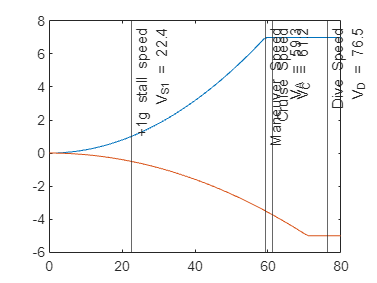

%n_lim_p = 5.3; n_lim_n = -2.65; % for utility class gliders

figure;
% plot upper and lower manuver limits
plot(V, n_lim_p); hold on
plot(V, n_lim_n);
%plot important V speeds
xline(V_A, "-", {"Maneuver Speed", sprintf("V_A = %.3g",V_A)}); % plot manuver speed
xline(V_S1, "-", {"+1g stall speed", sprintf("V_{S1} = %.3g",V_S1)}); % plot 1g stall speed
xline(V_C, "-", {"Cruise Speed", sprintf("V_C = %.3g",V_C)}); % plot cruise speed
xline(V_D, "-", {"Dive Speed", sprintf("V_D = %.3g",V_D)}); % plot dive speed

## Gust Diagram

% need to sort out units
% get gust velocity
if(alt < convlength(20000,"ft","m"))
    U_de_C_pos = convvel(66,"ft/s","m/s"); % positive gust for cruise
    U_de_C_neg = convvel(66,"ft/s","m/s"); % negative gust for cruise
elseif(alt < convlength(50000,"ft","m"))
    U_de_C_pos = convvel(66.67 - (.000833 .* alt),"ft/s","m/s"); % positive gust for cruise
    U_de_C_neg = convvel(66.67 - (.000833 .* alt),"ft/s","m/s"); % negative gust for cruise
else
    fprintf("altitude %g greater than %g not supported", alt, convlength(50000,"ft","m"))
end

psf2Pa = convpres(1,"psf","Pa"); % conversion foactor kts -> fps
% determine pi terms
mu_g = 2.*(W_TO./S) ./ (rho.*c_bar.*g) % random pi term used in calculation

mu_g = 99.1497

k_g = (.88 .* mu_g) ./ (5.3 + mu_g) % another random pi term

k_g = 0.8353

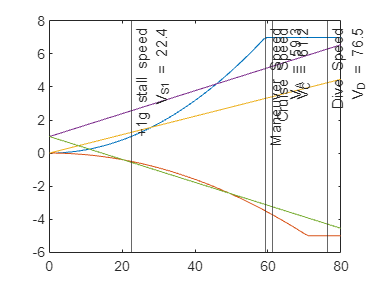

n_V_C_gust_pos = 1 + kts2fps .* psf2Pa .* (k_g .* U_de_C_pos .* V .* C_L_alpha) ./ (498 .* W_TO./S); % formula for gust load
n_V_C_gust_neg = 1 - kts2fps .* psf2Pa .* (k_g .* U_de_C_neg .* V .* C_L_alpha) ./ (498 .* W_TO./S); % formula for gust load


% CS-22
% get gust velocity
% NOTE: for now I am assuming design gust speed equals design cruise speed
if(alt < convlength(20000,"ft","m"))
    U_de_C_pos = 15; % positive gust for design cruise speed V_B(m/s)
    U_de_C_neg = 15; % negative gust for cruise (m/s)
elseif(alt < convlength(50000,"ft","m"))
    U_de_C_pos = 7.5; % positive gust for cruise (m/s)
    U_de_C_neg = 7.5; % negative gust for cruise (m/s)
else
    fprintf("altitude %g greater than %g not supported", alt, convlength(50000,"ft","m"))
end

[~, ~, ~, rho_SL] = atmosisa(0); % airdesnity at sea level kg/m^3
g = 9.81; % acceleration due to gravity in (m/s) 

% pi terms
mu = (2 * (W_TO./g)./S) ./ (rho .* c_bar * C_L_alpha);
H = (12.17 + .191 * mu) * c_bar;
k = .96 * mu ./ (H./c_bar) ./ (.475 + (mu ./ (H./c_bar)));

n_V_C_gust_pos = 1 + ((k/2) .* rho_SL .*  U_de_C_pos .* V .* C_L_alpha) ./ (W_TO ./ S);
n_V_C_gust_neg = 1 - ((k/2) .* rho_SL .*  U_de_C_pos .* V .* C_L_alpha) ./ (W_TO ./ S);

plot(V,1.25*(V/V_S1))

%plot curise gust line
plot(V,n_V_C_gust_pos);
plot(V,n_V_C_gust_neg);



% n_V_C_gust = 1 + psf2Pa .* (k_g .* U_de .* V .* C_L_alpha) ./ (498 .* W_TO./S)
% plot(V,n_V_C_gust)
